# Simulations of nitrification pathway

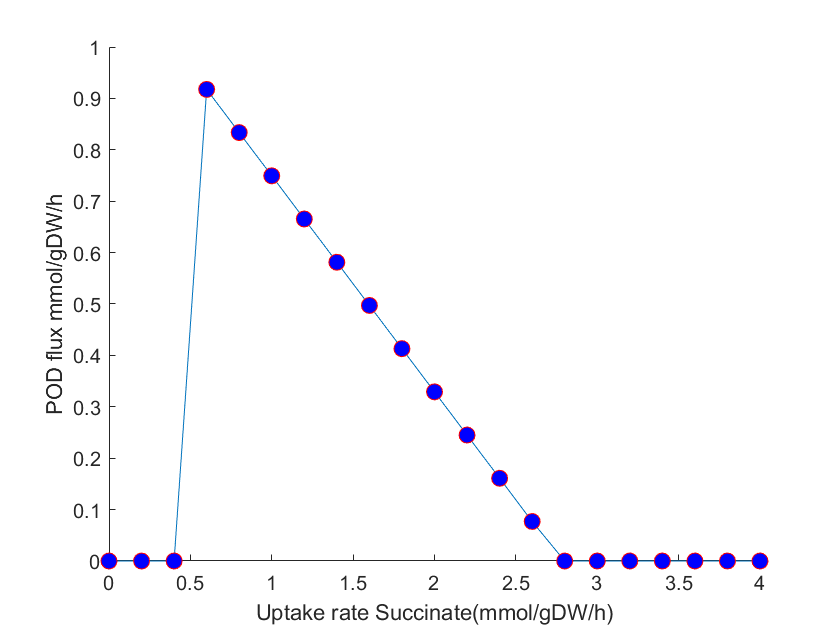

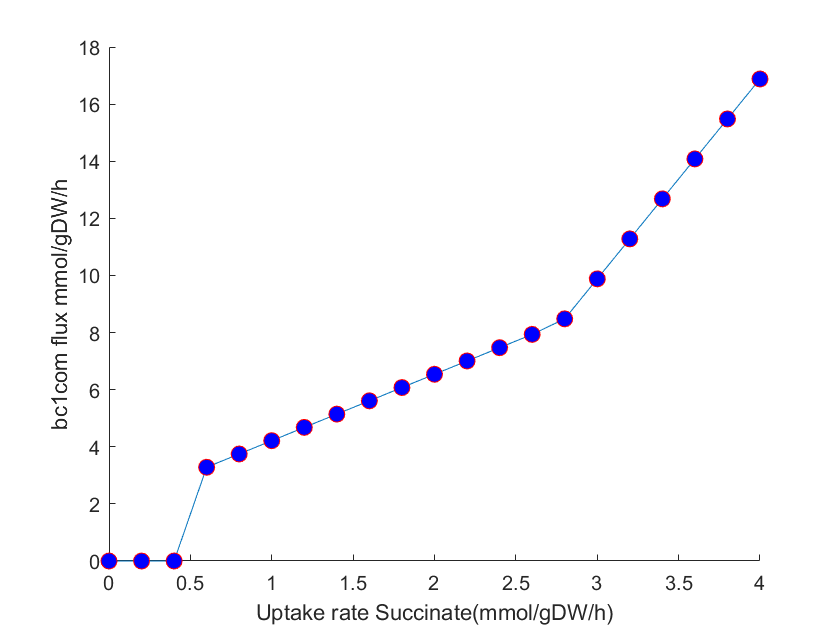

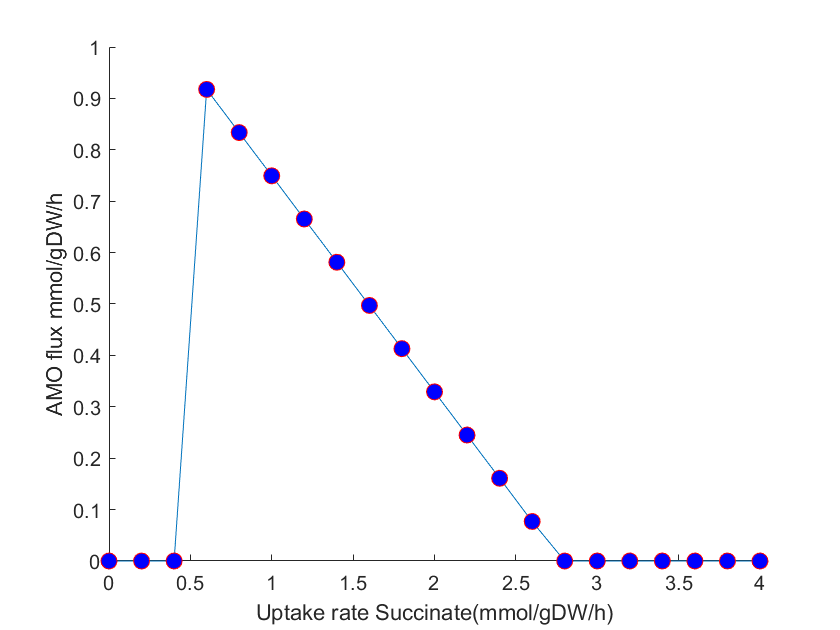

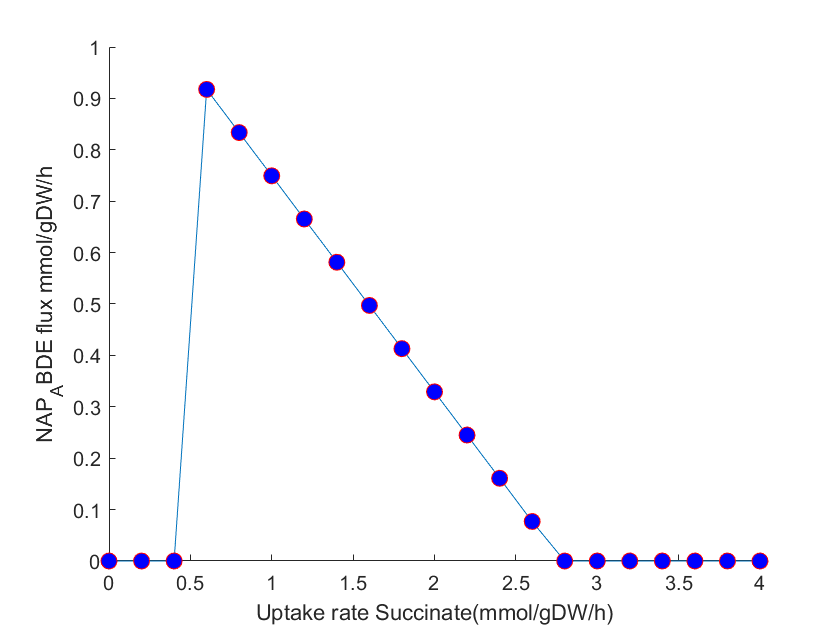

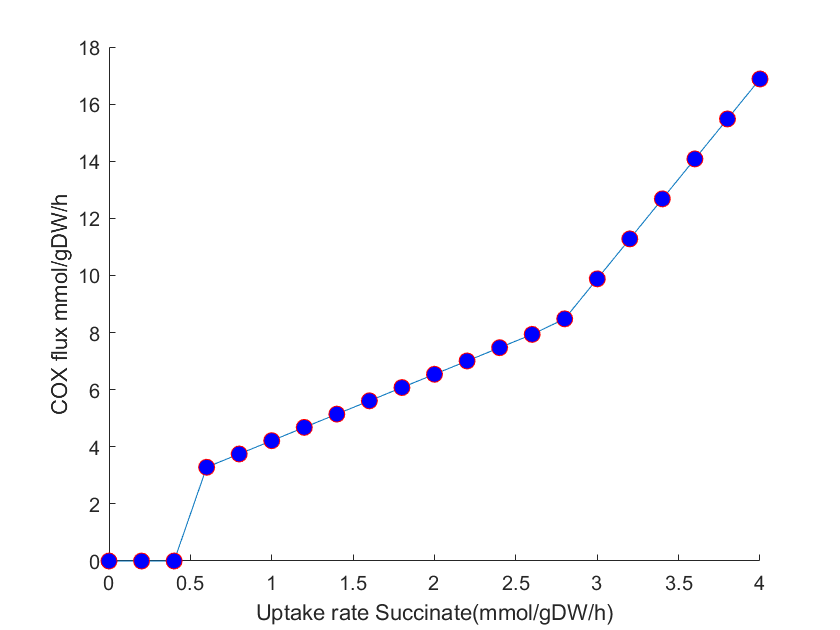

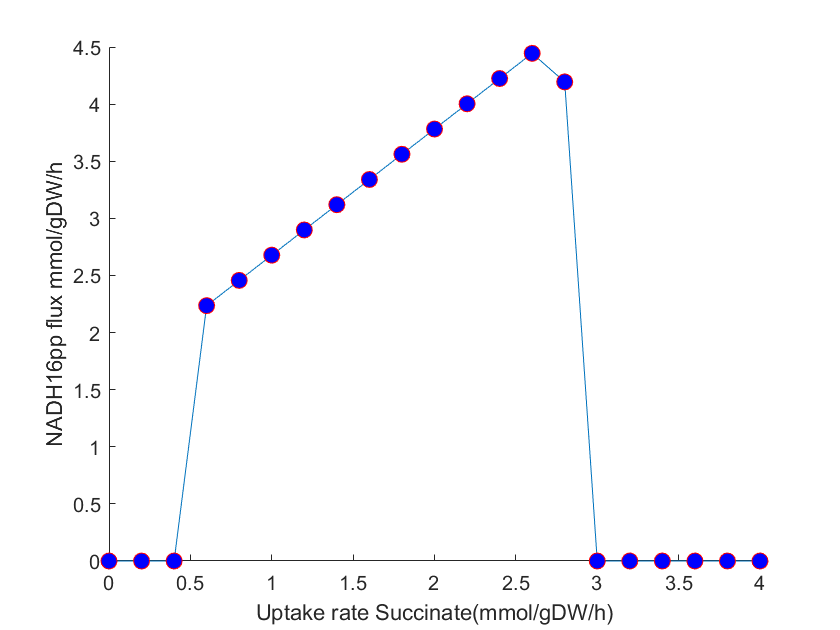

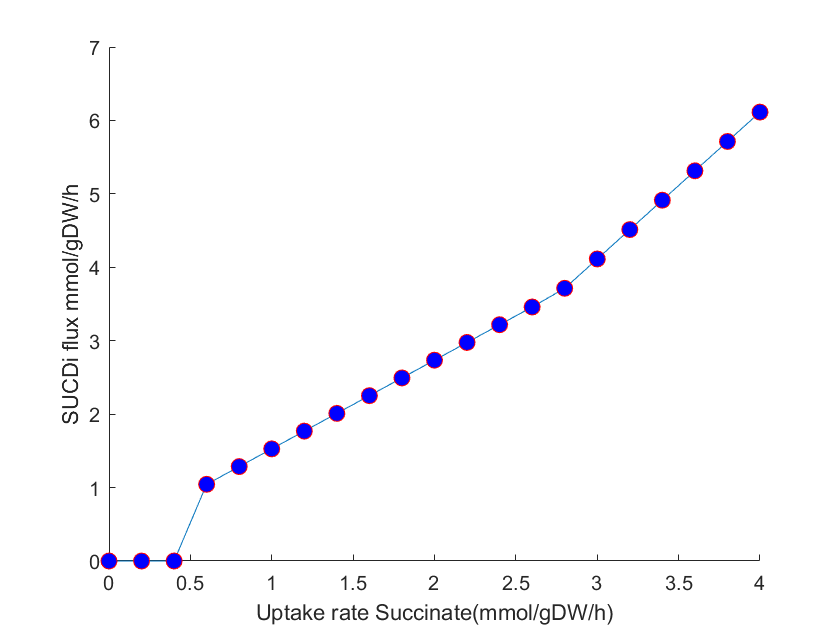

load('iGC1310');
model = iGC1310;

%Ammonium uptake fixed to -1
model = changeRxnBounds(model, {'EX_nh4_e'}, -1, 'l');

lbs = 0:0.2:4;
nLbs = length(lbs);
nRxns = length(model.rxns);
fluxMatrix   = zeros(nRxns, nLbs);
growth_rates = zeros(1, nLbs);

% FBA analysis over succinate uptake range
for i = 1:nLbs
    lb = lbs(i);
    model = changeRxnBounds(model, 'EX_succ_e', -1*lb, 'l');
    FBA = optimizeCbModel(model);
  
    if isempty(FBA) || ~isfield(FBA,'f') || isnan(FBA.f)
        growth = 0;
        X = zeros(nRxns,1);
    else
        growth = FBA.f;
        X = FBA.x;
    end
    
    growth_rates(i) = growth;
    fluxMatrix(:, i) = X;     
end

rxnNames = {'POD','bc1com','AMO','NO3R1bpp','CytCOX','NADH16pp','SUCDi'};
yLabels  = {'POD flux mmol/gDW/h','bc1com flux mmol/gDW/h','AMO flux mmol/gDW/h',...
            'NAP_ABDE flux mmol/gDW/h','COX flux mmol/gDW/h','NADH16pp flux mmol/gDW/h','SUCDi flux mmol/gDW/h'};

rxnIDs = zeros(size(rxnNames));
for k = 1:numel(rxnNames)
    rxnIDs(k) = findRxnIDs(model, rxnNames{k});
end

% plotting loop 
for k = 1:numel(rxnIDs)
    rid = rxnIDs(k);
    if rid == 0
        warning('Reaction %s not found in model. Skipping plot.', rxnNames{k});
        continue
    end
    flux = fluxMatrix(rid, :);
    
    figure;
    hold on;
    plot(lbs, flux, '-');                                
    plot(lbs, flux, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
    xlabel('Uptake rate Succinate(mmol/gDW/h)');
    ylabel(yLabels{k});
    hold off;

end